# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL -  A.Y. 2024/2025

# Full Examination

**June 20, 2025**

# Part 1 - MATLAB Grader - Exercise 1- A Simple Linear Model for a Swinging

## Introduction: Physics of Swinging

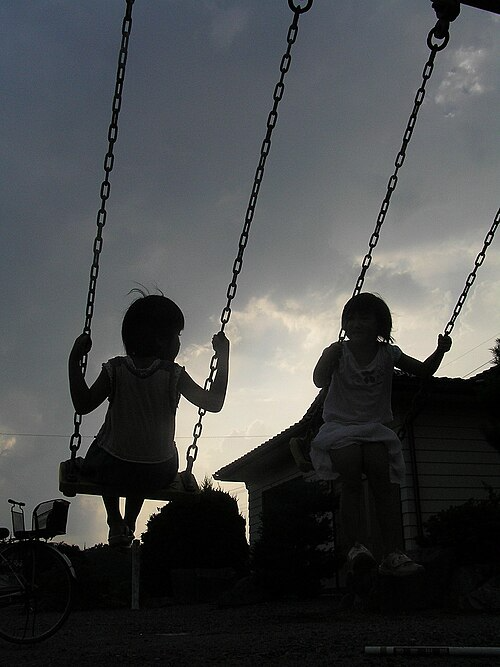

A swing is a seat or platform suspended from chains, ropes, or bars, allowing people to swing back and forth for fun or relaxation. Commonly found in playgrounds, backyards, gardens, and homes, swings operate like pendulums around a fixed pivot.

 As a rider swings down, their gravitational potential energy converts into kinetic energy and back to potential on the upswing. Over time, the motion diminishes due to air resistance and friction. To maintain swinging, energy is added either by pushing the swing or by the rider in a "pumping" motion, alternating between leaning back with extended legs and sitting upright with legs tucked.

## A Simplified, Linear Model for a Swinging

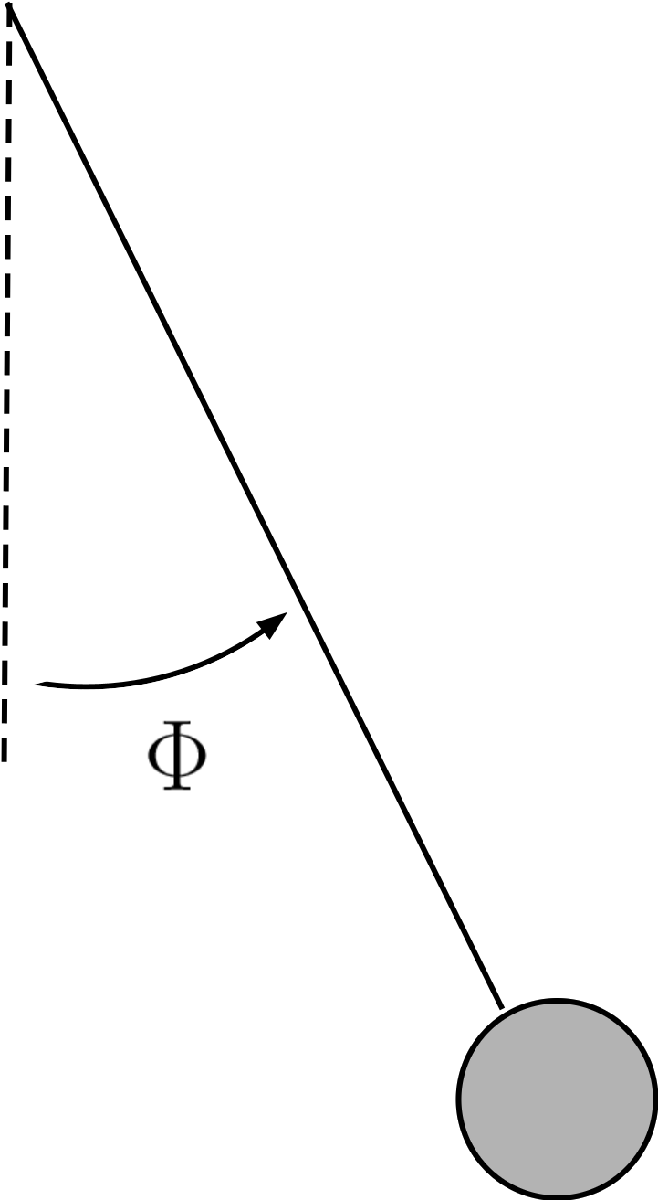

**A simplified model of a swing: a simple pendulum.**

 It is natural to push the swing with a period coinciding with the swing's period of oscillation. In this way, with small amounts of force greater than friction, the swing angle can be increased considerably. In this case, (which usually coincides with reality) the system is said to be in parametric resonance. In formulae, for small oscillations, the differential equation describing the swing's dynamics is:


$$\ddot{\Phi}(t) +b\,\dot{\Phi}(t) + \omega^2_0\,\Phi(t) = T\,\cos \big(\omega\,t \big) \cdot \mathbf{1}(t) \qquad (+)$$


where:

- $b$ is the coefficient of viscous friction;

- $\omega_0$ is the angular velocity of the natural oscillator;

- $\omega$ is the angular velocity of the forcing torque (generated by the thrust exerted by the movement of the legs);

- $T$ is the maximum value of the forcing torque.

- As usual, $\mathbf{1}(t)$ is the unit step function.

## Assignment

Your code shall:

- Define the symbolic variables **s** and **t**, corresponding respectively to the complex variable $s$ and the real variable $t$;

- Define the parameters $b$, $T$, and $\omega_0$ as symbolic variables, named `b`, `T`, `omega0`;

- Determine a state-space description for the dynamic system, using as state variables $\big[x_1(t)\,,\;x_2(t) \big]^{\top} = \big[\Phi(t)\,,\; \dot{\Phi}(t) \big]^{\top}$. The input is $u(t) = T\,\cos\big(\omega\,t \big)\cdot 1(t)$, and the output is $y(t) = \Phi(t)$.

- Save the resulting matrices $A,\,B,\,C$, and $D$ using the symbolic variables `symA`, `symB`, `symC`, and `symD`;

- Determine the transfer function corresponding to the state-space description just computed. Assign the resulting symbolic expression to the symbolic variable `symTs`.

- Using the transfer function `symTs` and the Laplace transform, compute the forced output movement for the system, corresponding to the given input $u(t) = T\,\cos\big(\omega\,t \big)\cdot 1(t)$. Save the resulting time variable $y(t)$ as the symbolic variable `yt`.

- Divide the expression of `yt` into two different terms: in the first one (named `y_transient`), insert the transient contributions you find by analysing `yt`, whereas in the second term(`y_steadystate`), put every steady-state contribution you found in `yt`. 

## Solution

% --- 1st bullet point ---
syms s t
% --- 1st bullet point ---

% --- 2nd bullet point ---
syms omega0 T b
% --- 2nd bullet point ---

% --- 3rd & 4th bullet points ---
% NB you don't need to use sym(): some elements of symA matrix are
% symbolic variables, thus symA is automatically a symbolic variable
symA = [0, 1;
        -b, -omega0^2]

$$symA = \left(\begin{array}{cc} 0 & 1\\ -b & -{\omega_{0}}^{2} \end{array}\right)$$

% you must declare symB as symbolic variable
symB = sym([0; +1])

$$symB = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

% you must declare symC as symbolic variable
symC = sym([1 0])

$$symC = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

% you must declare symD as symbolic variable
symD = sym(0)

$$symD = 0$$

% you don't need to declare sIA as symbolic variable, nor siAinv
sIA = s*eye(2)-symA;
siAinv = inv(sIA);
% --- 3rd & 4th bullet points ---


% ---- 5th bullet point ----
symTs = symC*siAinv*symB+symD

$$symTs = \frac{1}{{\omega_{0}}^{2}\,s+s^{2}+b}$$

% ---- 5th bullet point ----


% ---- 6th bullet point ----
syms omega
% *** You must declare a new symbolic variable or you are not able to ***
% *** describe the input variable ut.                                 ***

ut = T*cos(omega*t);
Us = laplace(ut,t,s);
Ys = symTs * Us

$$Ys = \frac{T\,s}{\left(\omega^{2}+s^{2}\right)\,\left({\omega_{0}}^{2}\,s+s^{2}+b\right)}$$

yt = ilaplace(Ys)

$$yt = \begin{array}{l} \frac{T\,b\,\cos\left(\omega \,t\right)-T\,\omega^{2}\,\cos\left(\omega \,t\right)+T\,\omega \,{\omega_{0}}^{2}\,\sin\left(\omega \,t\right)}{\sigma_{1}}-\frac{{\mathrm{e}}^{-\frac{{\omega_{0}}^{2}\,t}{2}}\,\left(\cosh\left(t\,\sigma_{3}\right)-\frac{\sinh\left(t\,\sigma_{3}\right)\,\left(\frac{{\omega_{0}}^{2}}{2}-\frac{T\,b\,{\omega_{0}}^{2}}{\sigma_{2}}\right)}{\sigma_{3}}\right)\,\sigma_{2}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b^{2}-2\,b\,\omega^{2}+\omega^{4}+\omega^{2}\,{\omega_{0}}^{4}\\ \sigma_{2}=T\,b-T\,\omega^{2}\\ \sigma_{3}=\sqrt{\frac{{\omega_{0}}^{4}}{4}-b} \end{array}$$

% ---- 6th bullet point ----

### Important Note

Let's analyse the expression of `yt`: there are two different contributions (two big fractional terms)

- the **first** **part** contains only terms with **sinusoidal** or **cosinusoidal** **functions**: it is undoubtedly a** steady-state contribution**!

- the **second** **contribution** contains the **vanishing** **exponential** **term** $e^{- \,\displaystyle \frac{\omega_0^2\,t}{2} }$: it is the **transient** **part** of the output `yt`.

How can the transient part be programmatically separated from the steady-state contribution?

- You may rely on some MATLAB commands, such as `partfrac( )` or `residue( )`. Both these MATLAB functions allow the computation of the so-called "Partial Fraction Decomposition", i.e. the decomposition of the expression of a Laplace transform in a sum of elementary Laplace transforms (refer to the **Part "Laplace Transform", pages 35-48 **of the course material ).

- For details on the `partfrac `function and examples, refer to the online [MATLAB documentation](https://uk.mathworks.com/help/symbolic/sym.partfrac.html). 

- For details on the `residue `function and examples, refer to the online [MATLAB documentation](https://uk.mathworks.com/help/matlab/ref/residue.html?searchHighlight=residue&s_tid=srchtitle_support_results_1_residue). 

- For a few application examples, refer for example [here](https://uk.mathworks.com/matlabcentral/answers/489597-inverse-laplace-transform-there-has-to-be-a-better-way) (for partfrac) or [here](https://lpsa.swarthmore.edu/LaplaceXform/InvLaplace/PFE1Matlab/html/PFE1.html) (for residue).

The **simplest way to separate** steady-state part from the transient terms relies on 

- printing the expression of yt in the MATLAB Command Window,  

                    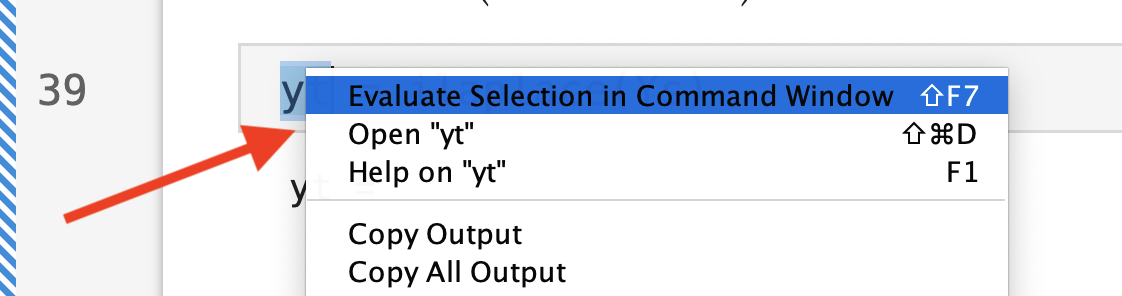

- identifying the terms corresponding, for example, to the steady-state output, 

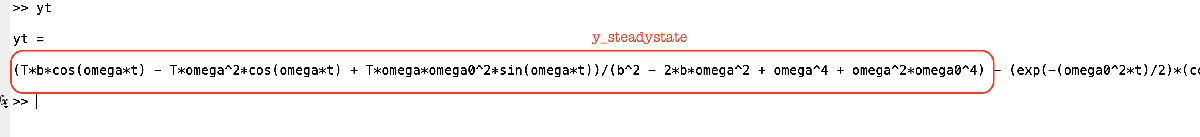

- selecting & copying the corresponding expression, 

- finally assigning to the requested symbolic variable in the live script


% ---------------------- 7th bullet point ----------------------
% ------------ copy&paste from the Command Window ------------
% 
% >> yt
% 
% yt =
% 
% (T*b*cos(omega*t) - T*omega^2*cos(omega*t) + T*omega*omega0^2*sin(omega*t))/(b^2 - 2*b*omega^2 + omega^4 + omega^2*omega0^4) - (exp(-(omega0^2*t)/2)*(cosh(t*(omega0^4/4 - b)^(1/2)) - (sinh(t*(omega0^4/4 - b)^(1/2))*(omega0^2/2 - (T*b*omega0^2)/(- T*omega^2 + T*b)))/(omega0^4/4 - b)^(1/2))*(- T*omega^2 + T*b))/(b^2 - 2*b*omega^2 + omega^4 + omega^2*omega0^4)
% 
% ------------ copy&paste from the Command Window ------------


y_steadystate = (T*b*cos(omega*t) - T*omega^2*cos(omega*t) + T*omega*omega0^2*sin(omega*t))/(b^2 - 2*b*omega^2 + omega^4 + omega^2*omega0^4) 

$$y\_steadystate = \frac{T\,b\,\cos\left(\omega \,t\right)-T\,\omega^{2}\,\cos\left(\omega \,t\right)+T\,\omega \,{\omega_{0}}^{2}\,\sin\left(\omega \,t\right)}{b^{2}-2\,b\,\omega^{2}+\omega^{4}+\omega^{2}\,{\omega_{0}}^{4}}$$


% let's determine the transient subtracting the steady-state contribution
% from the whole output expression
y_transient = yt-y_steadystate

$$y\_transient = \begin{array}{l} -\frac{{\mathrm{e}}^{-\frac{{\omega_{0}}^{2}\,t}{2}}\,\left(\cosh\left(\sigma_{1}\right)-\frac{\sinh\left(\sigma_{1}\right)\,\left(\frac{{\omega_{0}}^{2}}{2}-\frac{T\,b\,{\omega_{0}}^{2}}{\sigma_{2}}\right)}{\sqrt{\frac{{\omega_{0}}^{4}}{4}-b}}\right)\,\sigma_{2}}{b^{2}-2\,b\,\omega^{2}+\omega^{4}+\omega^{2}\,{\omega_{0}}^{4}}\\ \mathrm{where}\\ \sigma_{1}=t\,\sqrt{\frac{{\omega_{0}}^{4}}{4}-b}\\ \sigma_{2}=T\,b-T\,\omega^{2} \end{array}$$


% ---------------------- 7th bullet point ----------------------

% ============ END OF THE LIVE SCRIPT ============